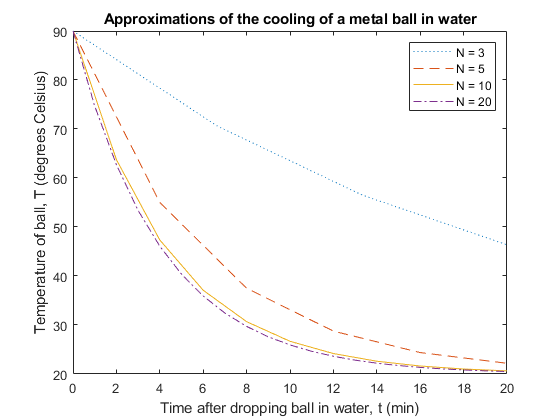

% MATLAB TEST QUESTION 2

% PLOTTING RESULTS

% plotting for when N = 3
N = 3;
[t, temp] = IEMsolver(N);
plot(t, temp, ':')
hold on

% plotting for when N = 5
N = 5;
[t, temp] = IEMsolver(N);
plot(t, temp, '--')

% plotting for when N = 10
N = 10;
[t, temp] = IEMsolver(N);
plot(t, temp, '-')

% plotting for when N = 20
N = 20;
[t, temp] = IEMsolver(N);
plot(t, temp, '-.')

title('Approximations of the cooling of a metal ball in water')
xlabel('Time after dropping ball in water, t (min)')
ylabel('Temperature of ball, T (degrees Celsius)')
legend('N = 3', 'N = 5', 'N = 10', 'N = 20')

% grid on


function [t, temp] = IEMsolver(N)
    % initialize given values
    T_a = 20;
    k = 0.25;
    T = 20;
    dt = T/N;   % calculating time step dt using T and N
    t = 0 : dt : T;     % creating vector of time values
    temp = NaN(1, length(t));   % initializing vector for solution
    temp(1) = 90;   % setting first value of solution vector to value of T_0
    for i = 2:length(t)
        m_prev = -k * (temp(i-1) - T_a);    % calculating slope at previous time value
        rough_val_cur = temp(i-1) + dt*m_prev;  % calculating approx. current value using EM
        m_cur = -k * (rough_val_cur - T_a);   % calculating current slope using the approximated current solution
        m = (m_prev + m_cur)/2;     % taking average of previous and current slope
        temp(i) = temp(i-1) + dt*m;     % calculating better approx. of current value using average slope
    end
end

I recommend using N = 10 time steps because it is twice as computationally efficient compared to N = 20 time steps, yet its approximations are off roughly (estimating from the graph) by a maximum of only 2 or 3 degrees Celsius.

I estimate that it takes the ball around 5 minutes to cool from 90 degrees C to 40 degrees C.